%Diseño Frecuencial
%kv=20  mdf=50 mgd=10 
s=tf('s');
G=(4/(s^2+2*s))

G =
 
      4
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



Gi=10*G

Gi =
 
     40
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



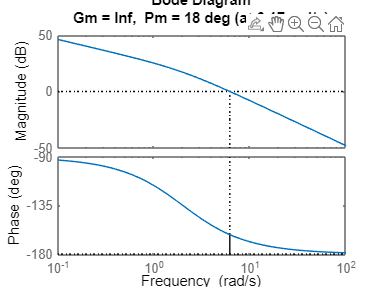

margin(Gi)

M=50-18+6 %margen de fase debe ser menor a 60

M = 38

alfa=(1-sin(0.66))/(1+sin(0.66)) %se deben convertir los radianes de M

alfa = 0.2398

bode(Gi)
wn %DEfinir wn con la grafica de margin
wm=1/(alfa)
Z=1/tf

%ejemplo para atraso
G1=zpk([],[0 -4 -1.667],80*1.667)

G1 =
 
       133.36
  -----------------
  s (s+4) (s+1.667)
 
Continuous-time zero/pole/gain model.



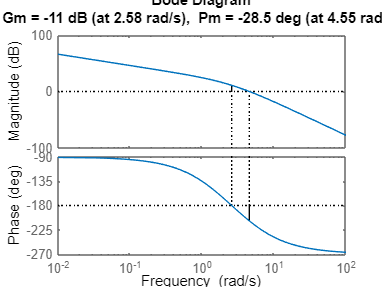

margin(G1)